# Mobile robot short Project

Authors: Pol Puigdemont & Marc Sardà

Link: /MATLAB Drive/MR_ShortProject_Puigde-Sarda

Given the kown workspace: Sensors_Data.mat, and  Enviroment.png

Answer the following question:

## Pose estimation given encoder data (10%)

Before start:

- Open the simulink_computations model EKF_Pose_estimation.slx and get familiar with: 'Where2Find_Code.pdf'. 

- Have a look to section See an animation of the file: 3_MR_SP_support.mlx 

Every thing is done, the exercise consist in compile in a mlx file all the concepts.

1.- Implement in this mlx file:

a) Pose_theoric, asumme no noise. (review **Mobile Robot Kinematics** folder)

b) Pose_estimation by adding noise in odometry. review **Pose uncertanty** folder)

c) Ricatti equation for estimating the covariance matrix representing the uncertanty in the robot pose. 

2.- Display in a figure:

a) x,y poses for both trajectories: theoric and estimated 

b) ellipses representing x,y uncertanty. Do it every 15-20 poses.

c) represent uncertanty in orientation by adding a isosceles triange in front of the robot the base 

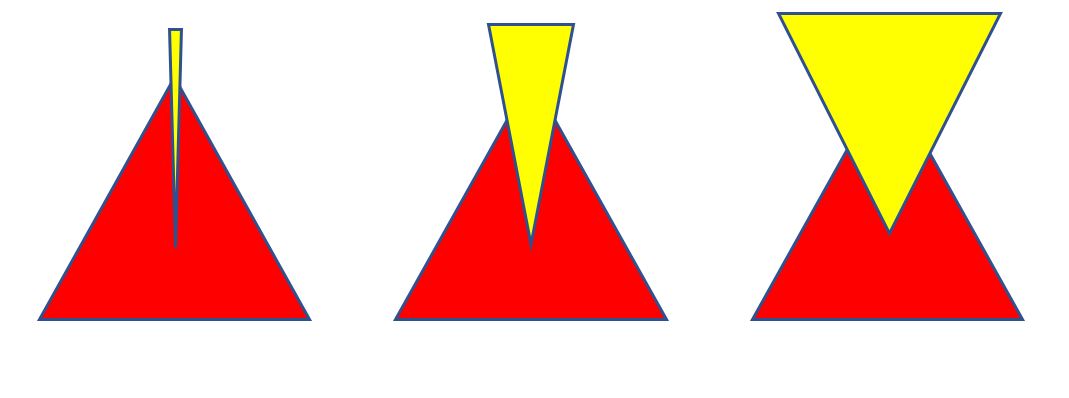

The robot will be represented by a triangle: Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]

Record a movie of the robot moving along the corridor displaying both trajectories.

 See: help VideoWriter to get familiar with the matlab functions

1.- Implement in this mlx file:

clear
load("Sensor_Data.mat");
simulink_computations = load('simulink_computations.mat');

Tf = 60.08;
Ts = 0.02;
W = 0.52;
Gear_ratio = 100;
r = 0.1;

R_inc = right_angular_speed(:, 2) / Gear_ratio * r * Ts;
L_inc = left_angular_speed(:, 2) / Gear_ratio * r * Ts;
R_acu = [right_angular_speed(:, 1), cumsum(R_inc)];
L_acu = [left_angular_speed(:, 1), cumsum(L_inc)];

t=linspace(0,Tf,length(R_acu(:,2)))';
delta_d=(R_inc+L_inc)/2;
delta_t=(R_inc-L_inc)/W;
Initial_position=[8.95,17.2,0];
Initial_orientation=3*pi/2;

a) Pose_theoric, asumme no noise. (review **Mobile Robot Kinematics** folder)

x_theoretical(1) = Initial_position(1);
y_theoretical(1) = Initial_position(2);
orientation(1) = Initial_orientation;
for Im=1:(length(t) - 1)
    x_theoretical(Im+1) = x_theoretical(Im) + delta_d(Im) * cos(orientation(Im));
    y_theoretical(Im+1) = y_theoretical(Im) + delta_d(Im) * sin(orientation(Im));
    orientation(Im+1) = orientation(Im) + delta_t(Im);
end
Pose_theoretical = [x_theoretical;y_theoretical;orientation];

b) Pose_estimation by adding noise in odometry. review **Pose uncertanty** folder)

x_estimated(1) = Initial_position(1);
y_estimated(1) = Initial_position(2);
orientation_estimated(1) = Initial_orientation;

for Im=1:(size(simulink_computations.Utilities.signals.values, 3))
    n_d = simulink_computations.Utilities.signals.values(1, 2, Im);
    n_th= simulink_computations.Utilities.signals.values(1, 1, Im);
    orientation_estimated(Im+1) = mod((orientation_estimated(Im)+delta_t(Im)+n_th), 2*pi);
    x_estimated(Im+1) = x_estimated(Im) + (delta_d(Im)+n_d) * cos(orientation_estimated(Im+1));
    y_estimated(Im+1) = y_estimated(Im) + (delta_d(Im)+n_d) * sin(orientation_estimated(Im+1));
    
end
Pose_estimated = [x_estimated;y_estimated;orientation_estimated];

c) Ricatti equation for estimating the covariance matrix representing the uncertanty in the robot pose.

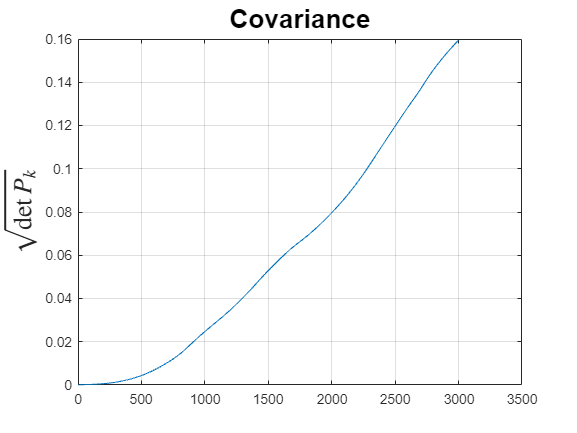

% vars precomputed in simulink computations
a(1, :) = 0;
pki = simulink_computations.Pk.signals.values;
for Im=1:3001
    a(Im, :)=sqrt(det(pki(:,:,Im)));
end

figure
values = 1:1:size(a, 1);
plot(values, a')
title ('Covariance',"FontSize",19)
ylabel('$\sqrt {\det {P_k}}$','Interpreter',"latex","FontSize",19)
grid on

2.- Display in a figure:

a) x,y poses for both trajectories: theoric and estimated 

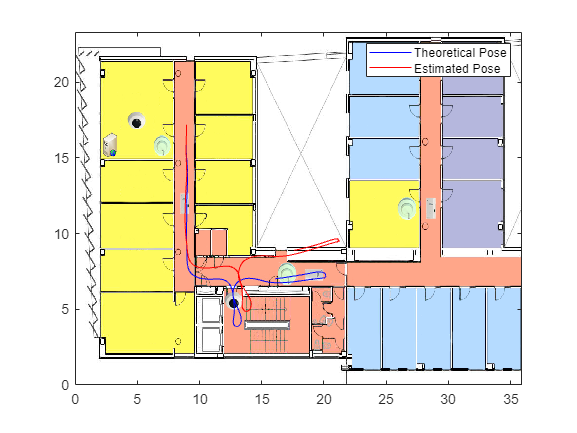

figure1=figure;
Im = imread('Enviroment.png');
x = [0 35.9];
y = [23.31 0];
image(Im,'XData',x,'YData',y);
axis xy;
hold on
plot(Pose_theoretical(1, :),Pose_theoretical(2, :), 'b')
plot(Pose_estimated(1,:), Pose_estimated(2,:), 'r')
legend('Theoretical Pose','Estimated Pose')

b) ellipses representing x,y uncertanty. Do it every 15-20 poses.

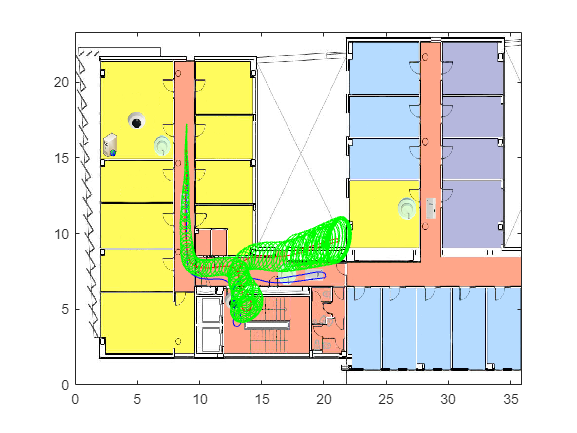

close all
Im = imread('Enviroment.png');
x = [0 35.9];
y = [23.31 0];
image(Im,'XData',x,'YData',y);
axis xy;
hold on

plot(Pose_theoretical(1, :),Pose_theoretical(2, :), 'b')
plot(Pose_estimated(1,:), Pose_estimated(2,:), 'r')
len=size(simulink_computations.Utilities.signals.values, 3);

% from pki value computed on simulink displays elipse each 20 iterations
pki = simulink_computations.Pk.signals.values;
for Im=1:20:size(pki, 3)
    elipse = pki(:,:,Im);
    plot_ellipse(elipse(1:2,1:2),[x_estimated(1,Im), y_estimated(1, Im)],'g');
end

c) represent uncertanty in orientation by adding a isosceles triange in front of the robot the base 

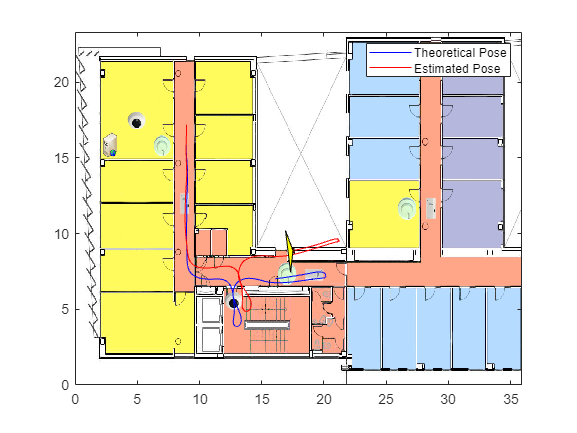

close all
axis equal
Im = imread('Enviroment.png');
x = [0 35.9];
y = [23.31 0];
image(Im,'XData',x,'YData',y);
axis xy;
hold on

plot(Pose_theoretical(1, :),Pose_theoretical(2, :), 'b')
plot(Pose_estimated(1,:), Pose_estimated(2,:), 'r')

Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
triangular_shape = Robot;
robot_drawing = [];
triangle_drawing = [];


for Im = 1:20:size(pki, 3)
    delete(robot_drawing);
    delete(triangle_drawing);
    robot_localization = transl(x_estimated(Im), y_estimated(Im), 0) * trotz(orientation_estimated(Im)) * Robot';
    triangular_shape = Robot;
    width = pki(3,3,Im);
    triangular_shape(1, 2) = -width*100/2;
    triangular_shape(3, 2) = width*100/2;
    triangle_localization = transl(x_estimated(Im), y_estimated(Im), 0) * trotz(orientation_estimated(Im)) * transl(0.5, 0, 0) * trotz(180, 'deg') *  triangular_shape';

    robot_drawing = patch(robot_localization(1, :), robot_localization(2, :), 'r');
    triangle_drawing = patch(triangle_localization(1,:), triangle_localization(2,:), 'y');
    pause(0.01)
end

legend('Theoretical Pose','Estimated Pose')

## Mapping (10%)

Make a movie of laser data in Robot reference frame. See the video  of ATENEA: [Movie of the Laser Data seen in Robot Reference FrameURL](https://atenea.upc.edu/mod/url/view.php?id=3257292)

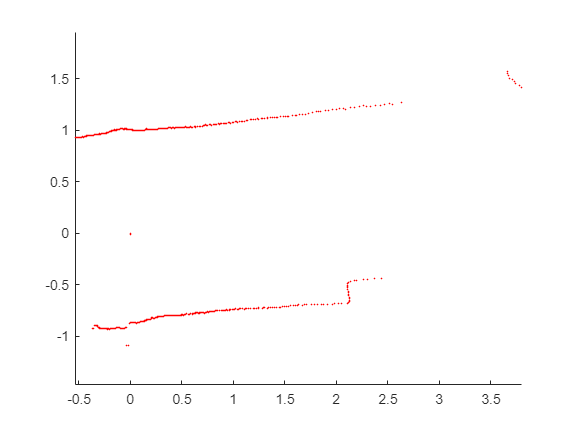

load('Laser_Data_CV__d_b.mat')
laser_data = polar_laser_data(:, 2:end-1)/1000;
angles = linspace(-120*pi/180, 120*pi/180, size(laser_data, 2));
laser_map = [];
close all
figure
hold on
axis equal
for i = 1:size(laser_data, 1)
    delete(laser_map)
    x = laser_data(i, :) .* cos(angles);
    y = laser_data(i, :) .* sin(angles);
    laser_map = scatter (x, y, 0.5, 'red');
    pause(0.1)
end

Make a video of laser data in Wordl Reference frame. Use here the code of the last TODO Lab about laser data. 

Display laser data every 2.5 m and erasing the previous walls after 200ms for better understanding.

See the video: '3_mapping.mp4' for inspiration

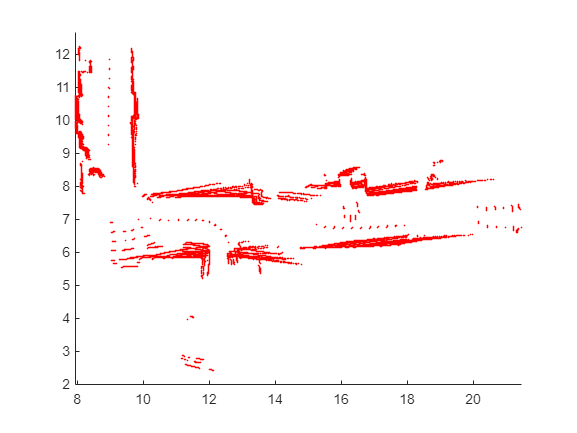

% Close existing figures
close all

% Create a new figure
figure
axis equal
hold on
count = 1;
m = size(polar_laser_data);
prev_display_x = x_theoretical(1);
prev_display_y = y_theoretical(1);
display_points = 0;
distance = @(x0, y0, x1, y1) sqrt((x1 - x0)^2 + (y1 - y0)^2);
tic;
frames = {};
laserplot = [];

for i = 1:m(1)
    d = distance(prev_display_x, prev_display_y, x_theoretical(20 * i), y_theoretical(20 * i));
    if d >= 2.5
        display_points = 1;
        prev_display_x = x_theoretical(20 * i);
        prev_display_y = y_theoretical(20 * i);
    end
    for j = 1:(m(2) - 1)
        if polar_laser_data(i, j) / 1000 > 0
            alpha = (j - 1) * 0.3515 * pi / 180;
            if alpha <= 240 / 2
                alpha = orientation(20 * i) + alpha - 122 * pi / 180;
            else
                alpha = orientation(20 * i) - alpha - 122 * pi / 180;
            end
            x2(count) = x_theoretical(20 * i) + polar_laser_data(i, j) / 1000 * cos(alpha);
            y2(count) = y_theoretical(20 * i) + polar_laser_data(i, j) / 1000 * sin(alpha);
            count = count + 1;

            if display_points == 1
                % Display scatter plot
                laserplot = scatter(x2, y2, 0.5, 'red');
                % Capture the current frame
                drawnow
                frame = getframe(gcf);
                frames{end+1} = frame;  
                pause(0.01)
                display_points = 0;
            end

            elapsed_time = toc;

            if elapsed_time > 0.2
                % Reset variables
                % Clear the scatter plot
                delete(laserplot);
                x2 = [];
                y2 = [];
                count = 1;
                tic;
            end
        end
    end
end

% Create a video file from the captured frames
videoFile = VideoWriter('laser_video.avi', 'Uncompressed AVI');
videoFile.FrameRate = 1;  % Adjust the frame rate as desired
open(videoFile);
for i = 1:numel(frames)
    writeVideo(videoFile, frames{i});
end
close(videoFile);

## Occupancy grid (30%)

Use Breshehan algorithm to build the map. Do it only when Land Marks are avalaible and the trajectory have been corrected.

Use the idea behind the line tracing: Visit: https://es.wikipedia.org/wiki/Algoritmo_de_Bresenham

See: Mapping.mlx and '4_occupancy.mp4' for inspiration

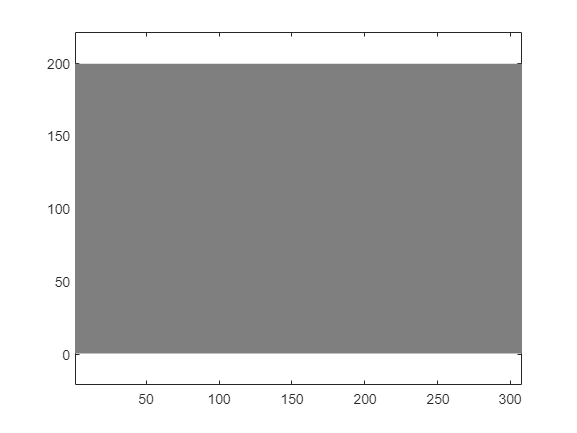

close all
A=ones(200,308);
s= pcolor (A);
colormap(gray(3))
s.EdgeColor = 'none';
axis equal

positions = [x_theoretical; y_theoretical; orientation]';

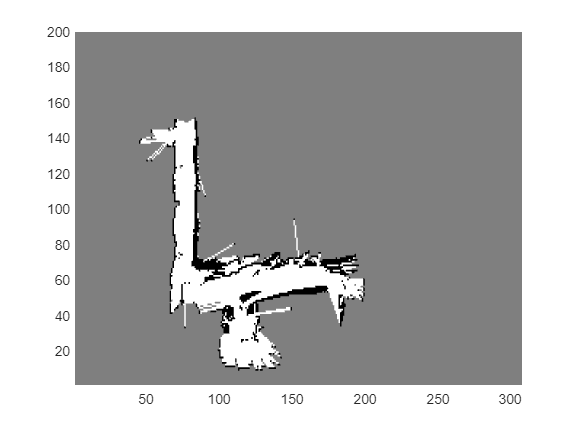

% tranformacion
x_topixel = 308/35.9;
y_topixel = 200/23.31;

for i=1:20:size(positions, 1)

    xNow = positions(i, 1);
    yNow = positions(i, 2);
    tNow = positions(i, 3);
    indice = floorDiv(i,20) + 1;

    x1 = round(xNow * x_topixel);
    y1 = round(yNow * y_topixel);
    
    if indice <= 149
        x = xNow + laser_data(indice, :) .* cos(angles + tNow);
        y = yNow + laser_data(indice, :) .* sin(angles + tNow);

        for j = 1: size(x, 2)
            x2 = round(x(j) * x_topixel);
            y2 = round(y(j) * y_topixel);

            if x1 ~= x2 && y1 ~= y2
                [x_line, y_line] = bresenham(x1, y1, x2, y2);
                for k=1: size(x_line, 1)
                    A(y_line(k), x_line(k)) = 2;

                end
                A(y2, x2) = 0;
            end

        end

        s= pcolor (A);
        colormap(gray(3));
        s.EdgeColor = 'none';
    
        pause(0.1);
    end

end

## Driving the Robot (20%)

Based on what you learn in motion arquitectures use the Goint2point for driving the robot. Use 'frontend.m' function to introduce way points such to recreate a trajectory similar to the past section.

Make a video displaying both trajectories: estimated and theoric. Add the ellipses to visualize uncertanty.

Notice that in this exercise the trajectoryies appear as the robot moves.

I_kine = @(v_x, psi,r,S) ...
[(1/r)*v_x+ (1/r)*S*psi (1/r)*v_x-(1/r)*S*psi];
w_s=I_kine(1,0,0.1,0.26)

w_s =     10    10



odo_vel = @(phi_r, phi_l,r,S,ts) ...
[(1/2)*r*(phi_r+phi_l)*ts (r/(2*S))*(phi_r-phi_l)*ts];
odo_vel(1,1,0.1,0.26,0.02)

ans =     0.0020         0



odo_cum = @(Delta_r, Delta_l,S) ...
[(1/2)*(Delta_r+Delta_l) (1/(2*S))*(Delta_r-Delta_l)];
odometry = odo_cum(-0.01,0.01,0.26)

odometry =          0   -0.0385



Pose_int=@(X_ant,odo) ...
[X_ant(1)+odo(1)*cos(X_ant(3)) ...
 X_ant(2)+odo(1)*sin(X_ant(3)) ...
 X_ant(3)+odo(2)];
Next_pose=Pose_int([0 0 0],odometry)

Next_pose =          0         0   -0.0385


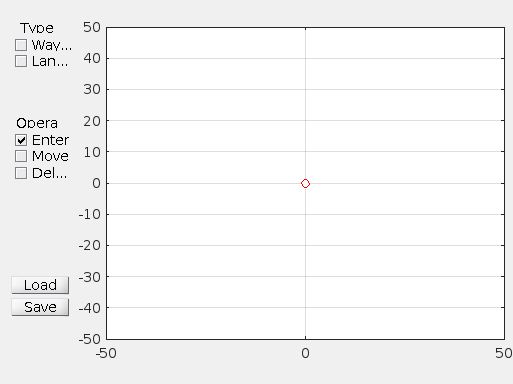

frontend

clf;
waypoints = load(['theoric_waypoints.mat']).wp

waypoints =          0   -0.2466    0.1233   -0.2466    6.2885   15.6597   19.9753   18.8656   21.7016   28.9766   30.4562   26.7571   27.2503   33.7855   42.0469   42.7867   37.7312   31.4427   25.7707
         0   -9.7962  -20.4545  -40.5172  -44.7492  -43.9655  -49.7649  -57.2884  -64.9687  -63.2445  -54.7806  -48.1975  -43.0251  -42.3981  -42.2414  -37.5392  -34.7179  -35.8150  -36.4420


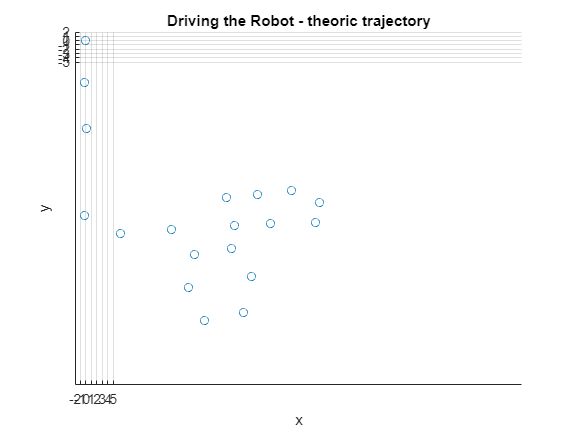

waypoint_index = 1;
startPose = [0,0,-pi/2]; % startPose [x y theta]
%waypoint_index = waypoint_index + 1;
goal = waypoints(:, waypoint_index); % goal position

Kv = 0.9; % Velocity Gain. Units (m/s)/m = [1/s]
Kh = 4; % Head Gain. Units [1/s]
r = 0.1; % wheels radius
S = 0.26; % half of the distance between the wheels' center  
ts = 0.02;% sample time

currentPose = startPose;
stop = false;

figure
hold on
scatter(waypoints(1, :), waypoints(2, :));
xlabel('x');
ylabel('y');
title('Driving the Robot - theoric trajectory')
grid
axis([-5 5 -5 5])
xticks(-5:5);
yticks(-5:5);

Robot_V= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
Robot_F = [1,2,3];
hr=[];
xlim([-2 80])
ylim([-80 2])
hold on

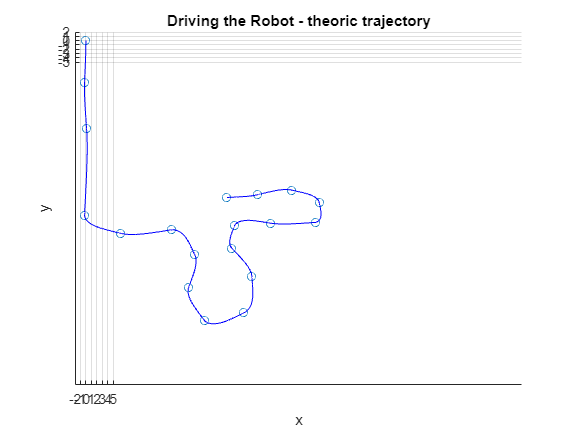

stop = logical
   1


while (~stop)
    delete (hr);
    currentdiff = goal' - currentPose([1,2]);
    throttle = sqrt(currentdiff(1)^2 + currentdiff(2)^2);
    if throttle < 0.1 %we can stop if distance error is less than 0.1
        if waypoint_index == size(waypoints, 2)
            stop = true
        else
            waypoint_index = waypoint_index + 1; % increment the waypoint index
            goal = waypoints(:, waypoint_index); % update the goal position
        end
    else
        velocity = throttle *  Kv;
        steering = atan2(currentdiff(2),currentdiff(1));
        psi = angdiff(steering,currentPose(3))*Kh;
        phi_l_r = I_kine(velocity,psi,r,S);
        deltas = odo_vel(phi_l_r(1),phi_l_r(2),r,S,ts);
        lastPose = currentPose;
        currentPose = Pose_int(currentPose,[deltas(1),deltas(2)]);
        pose = transl(currentPose(1),currentPose(2),0)* trotz(currentPose(3));
        Robot_tr=pose*Robot_V';% moving the robot 
        hr=patch(Robot_tr(1,:), Robot_tr(2,:),'b'); 
        pause(0.05);
        plot([lastPose(1),currentPose(1)],[lastPose(2),currentPose(2)],...
        'LineStyle',"-","Color",'blue');
    end
end

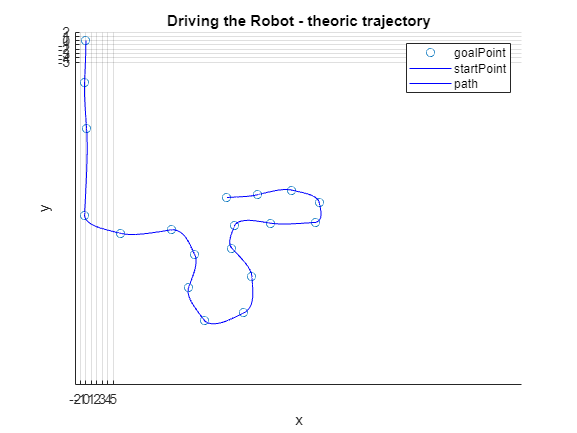

legend('goalPoint','startPoint','path');

clf;
waypoints = load('estimated_waypoints.mat').wp

waypoints =          0    0.1233    0.1233   -0.6165    3.2059   13.8101   21.5783   21.9482   20.5919   24.1677   34.7719   31.5660   28.9766   31.0727   51.6646   55.1171   48.8286   44.1430   36.6215   29.2232
         0  -10.3286  -20.6573  -29.8905  -41.1581  -39.7496  -41.9405  -50.8607  -56.9640  -64.6322  -61.1894  -51.6432  -42.5665  -37.4022  -39.2801  -32.3944  -27.2300  -30.6729  -28.7950  -30.6729


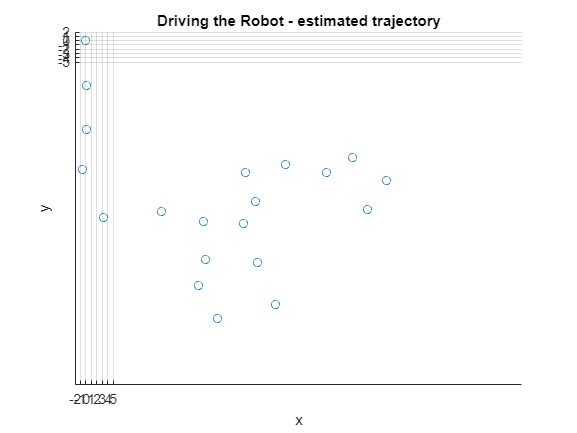

waypoint_index = 1;
startPose = [0,0,-pi/2]; % startPose [x y theta]
%waypoint_index = waypoint_index + 1;
goal = waypoints(:, waypoint_index); % goal position

Kv = 0.9; % Velocity Gain. Units (m/s)/m = [1/s]
Kh = 4; % Head Gain. Units [1/s]
r = 0.1; % wheels radius
S = 0.26; % half of the distance between the wheels' center  
ts = 0.02;% sample time

currentPose = startPose;
stop = false;

figure
hold on
scatter(waypoints(1, :), waypoints(2, :));
xlabel('x');
ylabel('y');
title('Driving the Robot - estimated trajectory')
grid
axis([-5 5 -5 5])
xticks(-5:5);
yticks(-5:5);

Robot_V= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
Robot_F = [1,2,3];
hr=[];
xlim([-2 80])
ylim([-80 2])
hold on

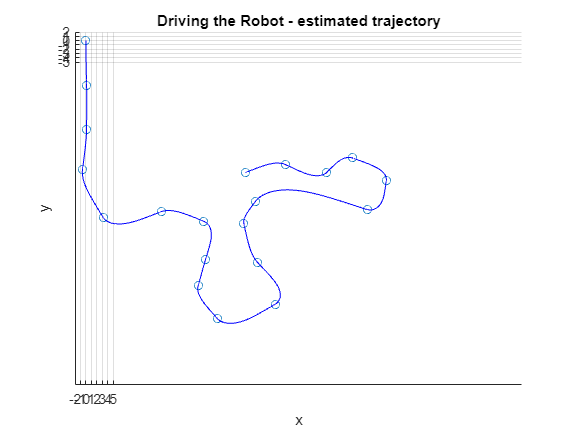

stop = logical
   1


while (~stop)
    delete (hr);
    currentdiff = goal' - currentPose([1,2]);
    throttle = sqrt(currentdiff(1)^2 + currentdiff(2)^2);
    if throttle < 0.1 %we can stop if distance error is less than 0.1
        if waypoint_index == size(waypoints, 2)
            stop = true
        else
            waypoint_index = waypoint_index + 1; % increment the waypoint index
            goal = waypoints(:, waypoint_index); % update the goal position
        end
    else
        velocity = throttle *  Kv;
        steering = atan2(currentdiff(2),currentdiff(1));
        psi = angdiff(steering,currentPose(3))*Kh;
        phi_l_r = I_kine(velocity,psi,r,S);
        deltas = odo_vel(phi_l_r(1),phi_l_r(2),r,S,ts);
        lastPose = currentPose;
        currentPose = Pose_int(currentPose,[deltas(1),deltas(2)]);
        pose = transl(currentPose(1),currentPose(2),0)* trotz(currentPose(3));
        Robot_tr=pose*Robot_V';% moving the robot 
        hr=patch(Robot_tr(1,:), Robot_tr(2,:),'b'); 
        pause(0.05);
        plot([lastPose(1),currentPose(1)],[lastPose(2),currentPose(2)],...
        'LineStyle',"-","Color",'blue');
    end
end

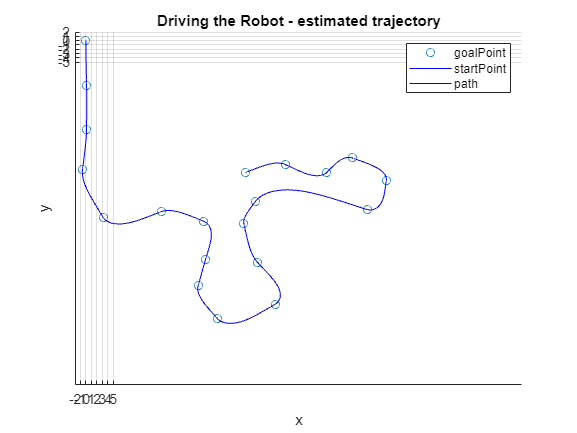

legend('goalPoint','startPoint','path');

## Localization (30%)

While driving the Robot in the last section Localize the Robot  by using the Similarity Transform. 

Visit again the folder 11_Localization for inspiration.

### Land Marks - Plot Land Marks

Use the given Land Marks. They are known. They can be extracter from laser data, there are easy algorithms for finding they, like corner detection, etc ...

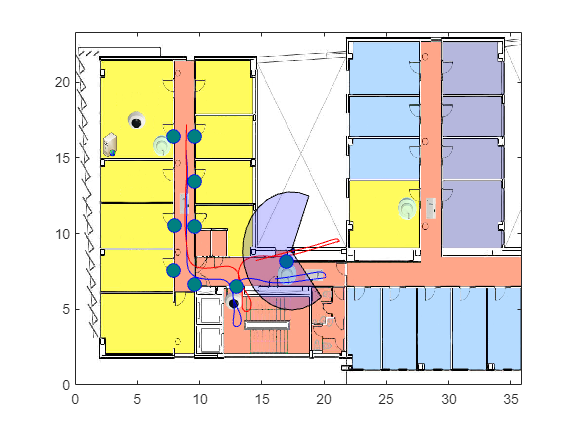

close all
axis equal
Im = imread('Enviroment.png');
x = [0 35.9];
y = [23.31 0];
image(Im,'XData',x,'YData',y);
axis xy;
hold on

% Coordenadas de los landmarks
Lmk= [7.934 16.431 0 1;...
      9.583 16.431 0 1;...
      9.584 13.444 0 1;...
      9.584 10.461 0 1;...
      7.973 10.534 0 1;...
      7.934  7.547 0 1;...
      9.584  6.654 0 1;...
     13.001  6.525 0 1;...
     17.007  8.136 0 1];

% Pintar los landmarks
sz = 100;
s=scatter(Lmk(:,1),Lmk(:,2),sz);
s.LineWidth = 0.6;
s.MarkerEdgeColor = 'b';
s.MarkerFaceColor = [0 0.5 0.5];

% Pintar las trayectorias
plot(Pose_theoretical(1, :),Pose_theoretical(2, :), 'b');
plot(Pose_estimated(1,:), Pose_estimated(2,:), 'r');


load('Laser_Data_CV__d_b.mat')
Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]';% The Robot icon is a triangle
Laser_Range=3.9; % meters
w=linspace(-30*pi/180,210*pi/180,20); %Laser foot print
s_x=Laser_Range*sin(w);
s_y=Laser_Range*cos(w);
Lfp.v=[[s_x 0];[s_y 0]]';
Lfp.f= [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 1];


hold on
axis([0 35.9 0 23.31]);
Robot_tr=eye(4)*Robot;
hr=patch(Robot_tr(1,1), Robot_tr(2,1),'b');
hlfp=patch('Faces',Lfp.f,'Vertices',Lfp.v,'FaceColor','blue','FaceAlpha',.2);
hll=line([0 0.01],[0 0.01],'Color','red','LineStyle','-');
hr=[];
hlft=[];
hll=[];
sz = 100; % to see thing biger
speed=10; % to speed up the animation
for Im=1:3000 % Use the for loop to see a movie
    k_m=mod(Im,speed);
    if k_m==0
        delete (hr); % Deleting figures and laser lines
        delete (hlfp);
        delete (hll)
        s=scatter(Lmk(:,1),Lmk(:,2),sz);
        s.LineWidth = 0.6;
        s.MarkerEdgeColor = 'b';
        s.MarkerFaceColor = [0 0.5 0.5];
        Robot_pose=transl(x_estimated(1,Im),y_estimated(1, Im),0)*trotz(orientation_estimated(1, Im));
        Robot_tr=Robot_pose*Robot;% moving the robot 
        Laser_fp=Robot_pose*transl(0.25,0,0)*[Lfp.v zeros(21,1) ones(21,1)]';
        axis([0 35.9 0 23.31]);
        hr=patch(Robot_tr(1,:), Robot_tr(2,:),'b');
        hlfp=patch('Faces',Lfp.f,'Vertices',Laser_fp(1:2,:)','FaceColor','blue','FaceAlpha',.2);
        Ls_lm_W=Robot_pose*[l_s_d(Im,:).*cos(l_s_b(Im,:));l_s_d(Im,:).*sin(l_s_b(Im,:)) ;zeros(1,9) ;ones(1,9)];
        position=transl(Robot_pose);
        hll=line([position(1) Ls_lm_W(1,1)...X's
                  position(1) Ls_lm_W(1,2)...
                  position(1) Ls_lm_W(1,3)...
                  position(1) Ls_lm_W(1,4)...
                  position(1) Ls_lm_W(1,5)...
                  position(1) Ls_lm_W(1,6)...
                  position(1) Ls_lm_W(1,7)...
                  position(1) Ls_lm_W(1,8)...
                  position(1) Ls_lm_W(1,9)],...
                  [position(2) Ls_lm_W(2,1)...%Y's
                  position(2) Ls_lm_W(2,2)...
                  position(2) Ls_lm_W(2,3)...
                  position(2) Ls_lm_W(2,4)...
                  position(2) Ls_lm_W(2,5)...
                  position(2) Ls_lm_W(2,6)...
                  position(2) Ls_lm_W(2,7)...
                  position(2) Ls_lm_W(2,8)...
                  position(2) Ls_lm_W(2,9)],'Color','red','LineStyle','-');
        
        pause(0.01);
    end
end

### Correct the noisy trajectory. 

Pay attention to the relationship of the variables

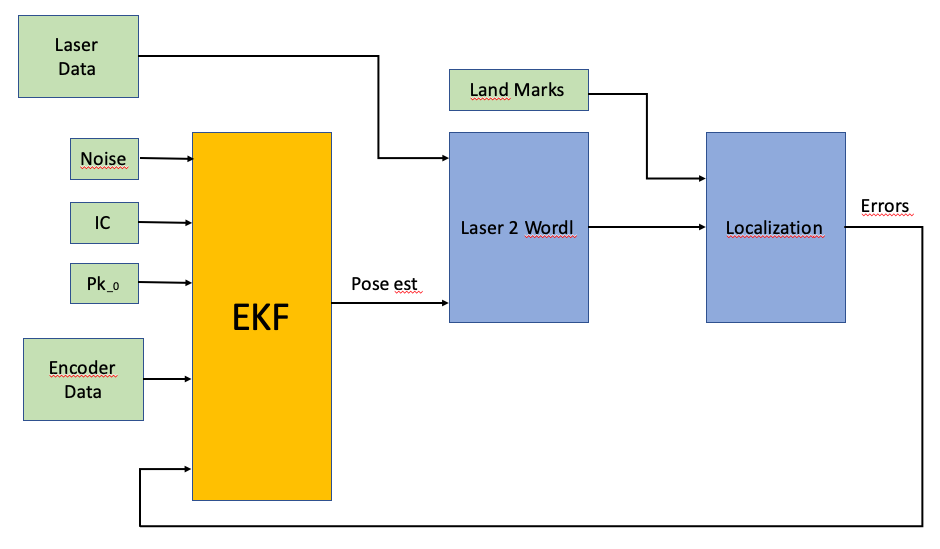

Update the estimated covarianze matrix by the sensor, knowing that the Laser scanner has and acuraccy 4 mm with a standard deviation of 0.2 mm.

1.- Display in a figure: the map, theoric trajectory (no noise) and the corrected trajectory.

2.- Make a 'log' with the following columns:  estimated noisy pose, corrected position, number of Land-marks seen,  and the errors and the covariance matrix Pk.

    Recalculate positions

x_calculated = Initial_position(1);
y_calculated = Initial_position(2);
o_calculated = Initial_orientation(1);
positions = [x_calculated, y_calculated, o_calculated];
log = [];

for Im=1:size(x_estimated, 2)-1
    counter = 0;
    A = [];
    B = [];
    for j=1:size(l_s_d, 2)
        
        if(l_s_d(Im, j) ~= 0)
            counter = counter + 1;
            ang_act = l_s_b(Im, j)+o_calculated;
            A = [A;[Lmk(j,1),Lmk(j,2),1,0]];
            A = [A;[Lmk(j,2),-Lmk(j,1),0,1]];

            x = x_calculated + cos(ang_act) * l_s_d(Im,j);
            y = y_calculated + sin(ang_act) * l_s_d(Im,j);
            B = [B; x; y];
        end
    end
    
    % we create the matrix once we have seen two landmarks
    if counter >= 2
        X = inv((A'*A))*A'*B;
        tx_ST = X(3);
        ty_ST = X(4);
        alpha_ST = atan2(X(2),X(1));
    else
        tx_ST = 0;
        ty_ST = 0;
        alpha_ST = 0;
    end

    % if correction factor is super small we remove it
    if -0.001 < tx_ST || tx_ST < 0.001
        tx_ST = 0;
    end
    if ty_ST < 0.001 || ty_ST > 1
        ty_ST = 0;
    end
    
    % subtracting the error
    x_calculated = x_calculated - tx_ST;
    y_calculated = y_calculated - ty_ST;
    o_calculated = o_calculated + alpha_ST;
    
    % correcting the noise
    n_d = simulink_computations.Utilities.signals.values(1, 2, Im);
    n_th= simulink_computations.Utilities.signals.values(1, 1, Im);

    % computing the odometry
    o_calculated = mod((o_calculated+delta_t(Im)+n_th), 2*pi);
    x_calculated = x_calculated + (delta_d(Im)+n_d) * cos(o_calculated);
    y_calculated = y_calculated + (delta_d(Im)+n_d) * sin(o_calculated);

    positions = [positions; x_calculated, y_calculated, o_calculated];
    log = [log; simulink_computations.Utilities.time(Im), x_estimated(Im), y_estimated(Im), x_calculated, y_calculated, counter, tx_ST, ty_ST, alpha_ST];

end

Recalculation demostration

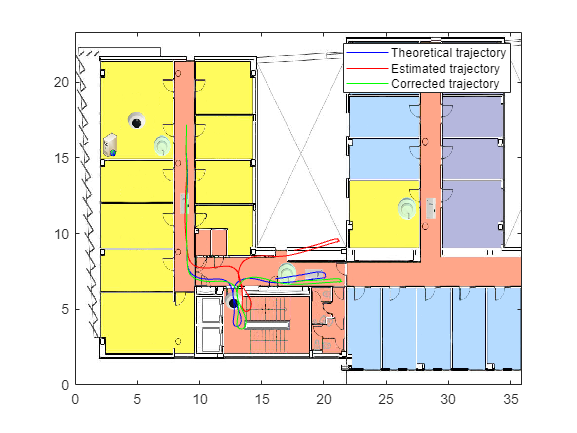

close all
Im = imread('Enviroment.png');
x = [0 35.9];
y = [23.31 0];
image(Im,'XData',x,'YData',y);
axis xy;
hold on
plot(Pose_theoretical(1, :),Pose_theoretical(2, :), 'b');
plot(Pose_estimated(1, :), Pose_estimated(2, :), 'r');
plot(positions(:, 1),positions(:, 2), 'g')
legend('Theoretical trajectory', 'Estimated trajectory', 'Corrected trajectory')

Save File

save('log_corrected_trajectory.mat', 'log');
save('log_corrected_trajectory.txt')
headers = ["time stamp", "Estimated noisy pose X", "Estimated noisy pose Y", " Corrected position X", "Corrected position Y", "n landmarks seen", "error in X", "error in Y", "error in orientation"];
log_corrected_trajectory = table(log);